## 円のプロット準備

angle = linspace(0,2*pi);
y_circle = r*cos(angle) + y_c;
z_circle = r*sin(angle) + z_c;

## グラフ設定

lw = 3;     % 文字の大きさ

## 位置

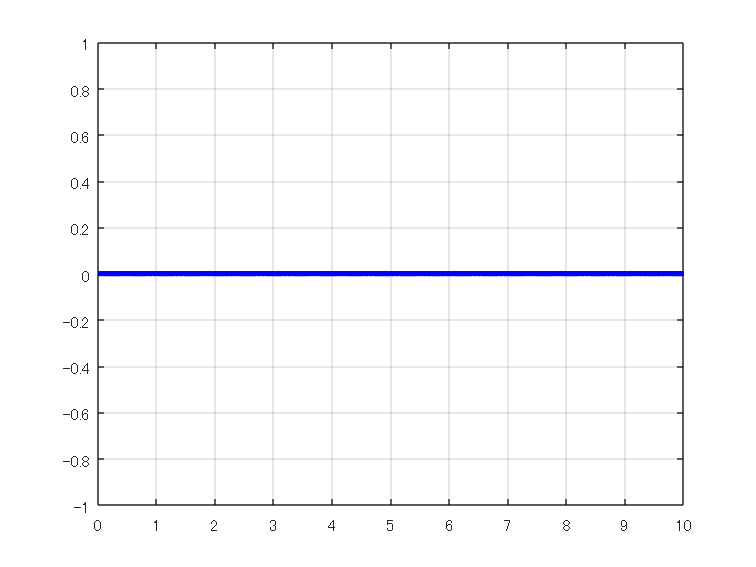

figure()
hold on; grid on; box on;
plot(position.Time,position.Data(:,1),'g','Color',[0 0 1],'LineWidth',lw,'DisplayName','x');

plot(p_d.Time,p_d.Data(:,1),'--','Color',[0 0 1],'LineWidth',1.5,'DisplayName','x_d');

名前 'p_d.Time' を解決できません。

plot(position.Time,position.Data(:,2),'g','Color',[0 1 0],'LineWidth',lw,'DisplayName','y');
plot(p_d.Time,p_d.Data(:,2),'--','Color',[0 1 0],'LineWidth',1.5,'DisplayName','y_d');
plot(position.Time,position.Data(:,3),'g','Color',[1 0 0],'LineWidth',lw,'DisplayName','z');
plot(p_d.Time,p_d.Data(:,3),'--','Color',[1 0 0],'LineWidth',1.5,'DisplayName','z_d');
pbaspect([1 1/1.618 1]); %黄金比
xlabel('Time [s]','Interpreter','latex','FontSize',fs);
ylabel('Position [m]','Interpreter','latex','FontSize',fs);
legend({'$x$','$x_d$','$y$','$y_d$','$z$','$z_d$'},'Interpreter','latex','FontSize',fs);
lgd = legend;
lgd.NumColumns = 3; %凡例の体裁を整えるコード(これがないと凡例が邪魔でグラフが見えなくなる)
lgd.Location = "northwest";
xlim([0 fs]);
ylim([0 4]);
set(gca,'Fontsize',fs);

figname= "Position";

if obst == "without_window"
    figpath = "figs/without_window";
end

if obst == "with_window"
    figpath = "figs/with_window";
end

% pdf（論文用），png（スライド用）， eps（念のため）の3種類で保存
exportgraphics(gcf,strcat(figpath,'/pdf/',figname,'.pdf'))
exportgraphics(gcf,strcat(figpath,'/png/',figname,'.png'))
exportgraphics(gcf,strcat(figpath,'/eps/',figname,'.eps'))

## 軌道(障害物あり)

if obst == "with_window"
figure()
hold on; grid on; box on;
axis equal
plot(position.Data(:,2),position.Data(:,3),'Color',[1 0 0],'LineWidth',lw);
plot(p_d.Data(:,2),p_d.Data(:,3),':','Color',[0 1 0],'LineWidth',lw);
plot(y_circle,z_circle,'LineStyle','-','Marker','none','Color',[0 0 1],'LineWidth',2)
pbaspect([1 1/1.618 1]); %黄金比
xlabel('Position $y$[m]','Interpreter','latex','FontSize',fs);
ylabel('Position $z$ [m]','Interpreter','latex','FontSize',fs);
legend({'$p$','$p_d$','Obstacle',},'Interpreter','latex','FontSize',fs);
lgd = legend;
lgd.NumColumns = 1; %凡例の体裁を整えるコード(これがないと凡例が邪魔でグラフが見えなくなる)
lgd.Location = "southwest";
xlim([-0.5 3]);
ylim([-0.5 3]);

set(gca,'Fontsize',fs,'XDir','reverse');

figname= "Trajectory";


if obst == "without_window"
    figpath = "figs/without_window";
end

if obst == "with_window"
    figpath = "figs/with_window";
end
% pdf（論文用），png（スライド用）， eps（念のため）の3種類で保存
exportgraphics(gcf,strcat(figpath,'/pdf/',figname,'.pdf'))
exportgraphics(gcf,strcat(figpath,'/png/',figname,'.png'))
exportgraphics(gcf,strcat(figpath,'/eps/',figname,'.eps'))
end

## 姿勢

figure()
hold on; grid on; box on;
plot(attitude.Time, attitude.Data(:,1),'LineWidth',lw,'DisplayName','psi');
plot(desired_attitude.Time, desired_attitude.Data(:,1),'--','LineWidth',1.5,'DisplayName','psi_d');
plot(attitude.Time, attitude.Data(:,2),'LineWidth',lw,'DisplayName','phi');
plot(desired_attitude.Time, desired_attitude.Data(:,2),'--','LineWidth',1.5,'DisplayName','phi_d');
plot(attitude.Time, attitude.Data(:,3),'LineWidth',lw,'DisplayName','theta');
plot(desired_attitude.Time, desired_attitude.Data(:,3),'--','LineWidth',1.5,'DisplayName','theta_d');
pbaspect([1 1/1.618 1]); %黄金比
xlabel('Time [s]','Interpreter','latex','FontSize',fs);
ylabel('Attitude [rad]','Interpreter','latex','FontSize',fs);
legend('$\alpha$','$\alpha_d$','$\beta$','$\beta_{d}$','$\gamma$','$\gamma_{d}$','Interpreter','latex','FontSize',fs);
lgd = legend;
lgd.NumColumns = 3; %凡例の体裁を整えるコード(これがないと凡例が邪魔でグラフが見えなくなる)
lgd.Location = "southeast";
xlim([0 fs])
if obst == "with_window"
ylim([-0.6 1])
end

if obst == "without_window"
    ylim([-0.5 0.3])
end

set(gca,'Fontsize',fs);

figname ="Attitude";

if obst == "without_window"
    figpath = "figs/without_window";
end

if obst == "with_window"
    figpath = "figs/with_window";
end
% pdf（論文用），png（スライド用）， eps（念のため）の3種類で保存
exportgraphics(gcf,strcat(figpath,'/pdf/',figname,'.pdf'))
exportgraphics(gcf,strcat(figpath,'/png/',figname,'.png'))
exportgraphics(gcf,strcat(figpath,'/eps/',figname,'.eps'))

## 速度

figure()
hold on; grid on; box on;
plot(velocity.Time,velocity.Data(:,1),'g','Color',[0 0 1],'LineWidth',lw,'DisplayName','x_dot');
plot(velocity.Time,velocity.Data(:,2),'g','Color',[0 1 0],'LineWidth',lw,'DisplayName','y_dot');
plot(velocity.Time,velocity.Data(:,3),'g','Color',[1 0 0],'LineWidth',lw,'DisplayName','z_dot');
pbaspect([1 1/1.618 1]); %黄金比
xlabel('Time [s]','Interpreter','latex','FontSize',fs);
ylabel('Velocity [m/s]','Interpreter','latex','FontSize',fs);
legend('$\dot{x}$','$\dot{y}$','$\dot{z}$','Interpreter','latex','FontSize',fs);
xlim([0 fs]);
if obst == "with_window"
ylim([-0.5 0.5]);
end

if obst == "without_window"
    ylim([-0.1 0.6])
end

set(gca,'Fontsize',fs);

figname = "Velocity";

if obst == "without_window"
    figpath = "figs/without_window";
end

if obst == "with_window"
    figpath = "figs/with_window";
end
% pdf（論文用），png（スライド用）， eps（念のため）の3種類で保存
exportgraphics(gcf,strcat(figpath,'/pdf/',figname,'.pdf'))
exportgraphics(gcf,strcat(figpath,'/png/',figname,'.png'))
exportgraphics(gcf,strcat(figpath,'/eps/',figname,'.eps'))

## ボディ速度

figure()
hold on; grid on; box on;
plot(body_velocity.Time,body_velocity.Data(:,1),'g','Color',[0 0 1],'LineWidth',lw,'DisplayName','v_x');
plot(body_velocity.Time,body_velocity.Data(:,2),'g','Color',[0 1 0],'LineWidth',lw,'DisplayName','v_y');
plot(body_velocity.Time,body_velocity.Data(:,3),'g','Color',[1 0 0],'LineWidth',lw,'DisplayName','v_z');
pbaspect([1 1/1.618 1]); %黄金比
xlabel('Time [s]','Interpreter','latex','FontSize',fs);
ylabel('Body Velocity [m/s]','Interpreter','latex','FontSize',fs);
legend('$v_x^b$','$v_y^b$','$v_z^b$','Interpreter','latex','FontSize',fs);
xlim([0 fs]);
if obst == "with_window"
ylim([-1 1.5]);
end

if obst == "without_window"
    ylim([-0.1 0.6])
end

set(gca,'Fontsize',fs);

figname = "Body_Velocity";

if obst == "without_window"
    figpath = "figs/without_window";
end

if obst == "with_window"
    figpath = "figs/with_window";
end
% pdf（論文用），png（スライド用）， eps（念のため）の3種類で保存
exportgraphics(gcf,strcat(figpath,'/pdf/',figname,'.pdf'))
exportgraphics(gcf,strcat(figpath,'/png/',figname,'.png'))
exportgraphics(gcf,strcat(figpath,'/eps/',figname,'.eps'))

##  角速度

% figure()
% hold on; grid on; box on;
% plot(angular_velocity.Time,angular_velocity.Data(:,3),'g','Color',[1 0 0],'LineWidth',lw,'DisplayName','r_yaw');
% plot(angular_velocity.Time,angular_velocity.Data(:,1),'g','Color',[0 0 1],'LineWidth',lw,'DisplayName','r_roll');
% plot(angular_velocity.Time,angular_velocity.Data(:,2),'g','Color',[0 1 0],'LineWidth',lw,'DisplayName','r_pitch');
% pbaspect([1 1/1.618 1]); %黄金比
% xlabel('Time [s]','Interpreter','latex','FontSize',fs);
% ylabel('Angular velocity [rad/s]','Interpreter','latex','FontSize',fs);
% legend('$\omega_{\alpha}^b$','$\omega_{\beta}^b$','$\omega_{\gamma}^b$','Interpreter','latex','FontSize',fs);
% xlim([0 fs]);
% if obst == "with_window"
% ylim([-2 3]);
% end
% 
% if obst == "without_window"
% ylim([-1.2 0.5])
% end
% 
% set(gca,'Fontsize',fs);
% 
% figname = "Angular_velocity";
% 
% 
% if obst == "without_window"
%     figpath = "figs/without_window";
% end
% 
% if obst == "with_window"
%     figpath = "figs/with_window";
% end
% % pdf（論文用），png（スライド用）， eps（念のため）の3種類で保存
% exportgraphics(gcf,strcat(figpath,'/pdf/',figname,'.pdf'))
% exportgraphics(gcf,strcat(figpath,'/png/',figname,'.png'))
% exportgraphics(gcf,strcat(figpath,'/eps/',figname,'.eps'))

## 推力

figure()
hold on; grid on; box on;
plot(thrust.Time,thrust.Data(:,3),'g','Color',[0 1 0],'LineWidth',lw,'DisplayName','thrust');
pbaspect([1 1/1.618 1]); %黄金比
xlabel('Time [s]','Interpreter','latex','FontSize',fs);
ylabel('Thrust [N]','Interpreter','latex','FontSize',fs);
legend({'$f^b$'},'Interpreter','latex','FontSize',fs);
lgd = legend;
lgd.NumColumns = 1; %凡例の体裁を整えるコード(これがないと凡例が邪魔でグラフが見えなくなる)
lgd.Location = "northeast";
xlim([0 fs]);
if obst == "with_window"
ylim([5 15]);
end

if obst == "without_window"
    ylim([7 16])
end

set(gca,'Fontsize',fs);
figname= 'Thrust';

if obst == "without_window"
    figpath = "figs/without_window";
end

if obst == "with_window"
    figpath = "figs/with_window";
end
% pdf（論文用），png（スライド用）， eps（念のため）の3種類で保存
exportgraphics(gcf,strcat(figpath,'/pdf/',figname,'.pdf'))
exportgraphics(gcf,strcat(figpath,'/png/',figname,'.png'))
exportgraphics(gcf,strcat(figpath,'/eps/',figname,'.eps'))

## トルク

figure()
hold on; grid on; box on;
plot(torque.Time,torque.Data(:,3),'g','Color',[1 0 0],'LineWidth',lw,'DisplayName','torque_yaw');
plot(torque.Time,torque.Data(:,1),'g','Color',[0 0 1],'LineWidth',lw,'DisplayName','torque_roll');
plot(torque.Time,torque.Data(:,2),'g','Color',[0 1 0],'LineWidth',lw,'DisplayName','torque_pitch');
pbaspect([1 1/1.618 1]); %黄金比
xlabel('Time [s]','Interpreter','latex','FontSize',fs);
ylabel('Torque [N$\cdot$m]','Interpreter','latex','FontSize',fs);
legend('$\tau_{\alpha}^b$','$\tau_{\beta}^b$','$\tau_{\gamma}^b$','Interpreter','latex','FontSize',fs);
xlim([0 fs]);
if obst == "with_window"
ylim([-0.6 0.4]);
end

if obst == "without_window"
    ylim([-0.3 0.1]);
end

set(gca,'Fontsize',fs);
figname= 'Torque';

if obst == "without_window"
    figpath = "figs/without_window";
end

if obst == "with_window"
    figpath = "figs/with_window";
end
% pdf（論文用），png（スライド用）， eps（念のため）の3種類で保存
exportgraphics(gcf,strcat(figpath,'/pdf/',figname,'.pdf'))
exportgraphics(gcf,strcat(figpath,'/png/',figname,'.png'))
exportgraphics(gcf,strcat(figpath,'/eps/',figname,'.eps'))